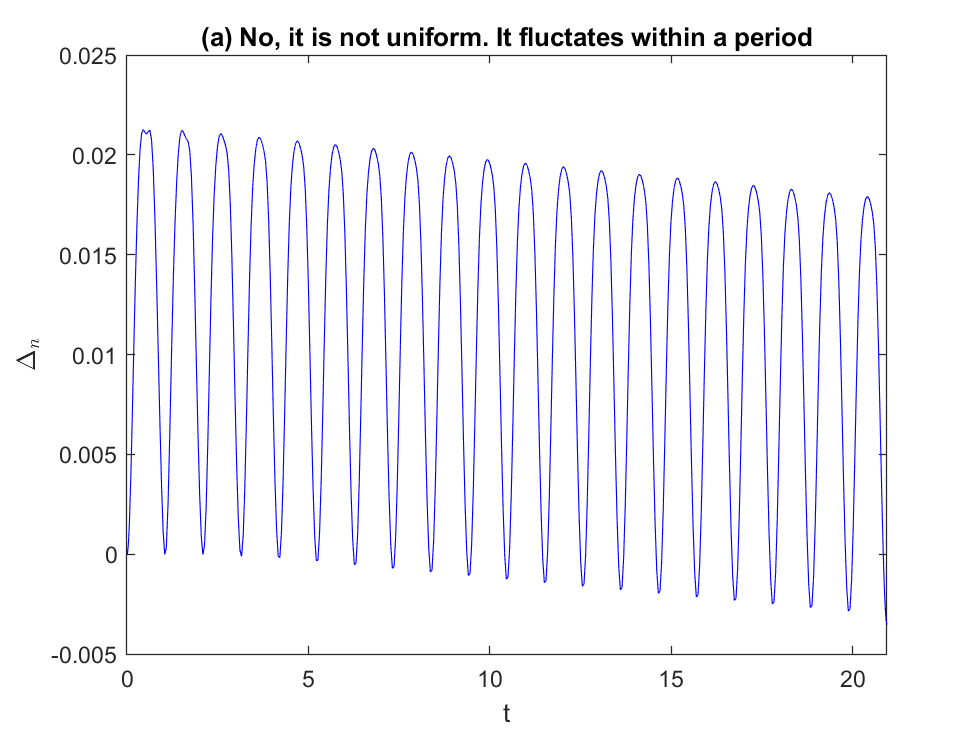

theta0 = 0.25;
thetad0 = 0;
g = 9.81;
omega2 = 9;
R = g/omega2;

[t, w] = pendulum(R, theta0, thetad0, 0);
% t, x, v
K = 0.5*R^2*w(:, 2).^2;
U = 0.5*omega2*R^2*sin(w(:,1)).^2;
E = K + U;
figure
plot(t, E/E(1)-1,'b-')
hold on
xlim([0 t(end)])
xlabel('t')
ylabel('$\Delta_n$','interpreter','latex')
title('(a) No, it is not uniform. It fluctates within a period')

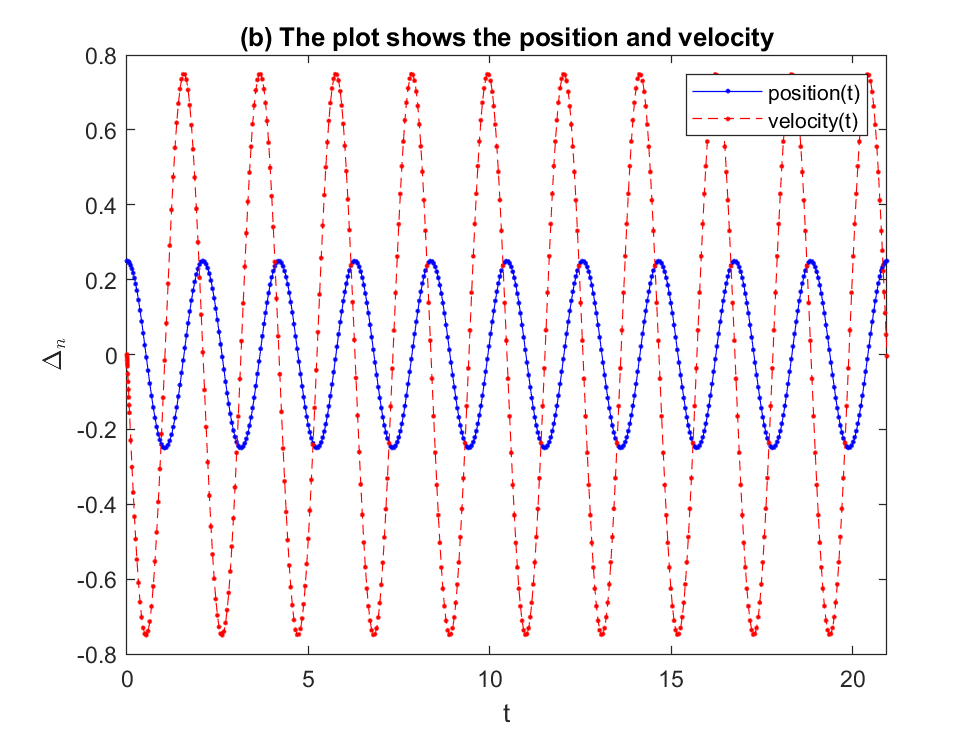

figure
plot(t, w(:,1),'b.-', t, w(:,2),'r.--')
hold on
xlim([0 t(end)])
xlabel('t')
ylabel('$\Delta_n$','interpreter','latex')
legend('position(t)', 'velocity(t)')
title('(b) The plot shows the position and velocity')

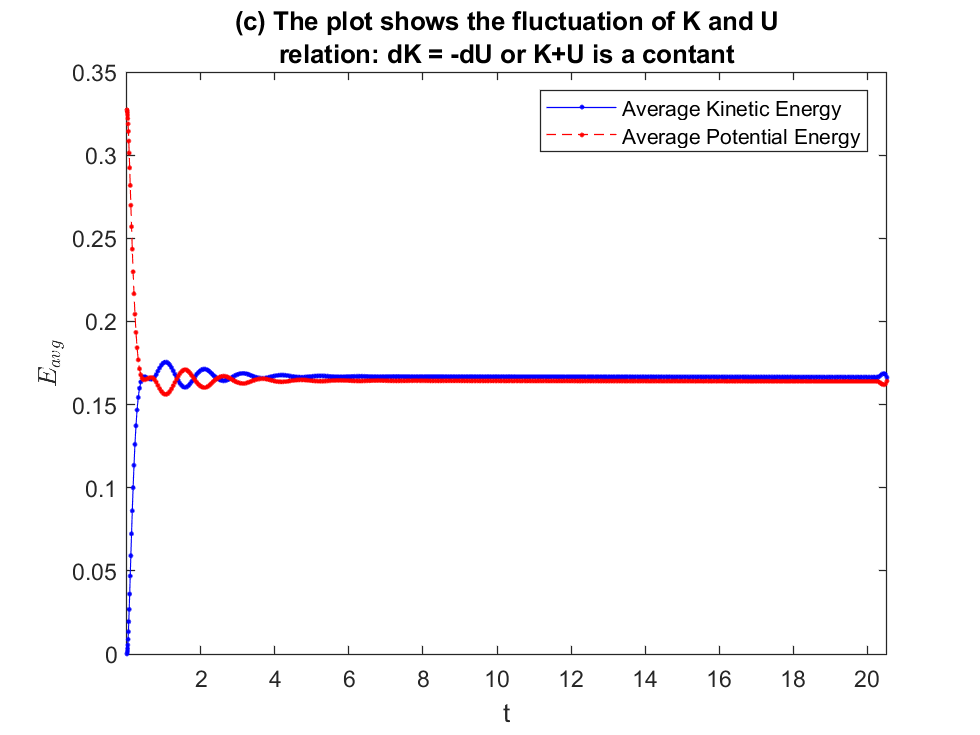

ind= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period = ind(3)-ind(2);
avgs = zeros(3, length(t)-period);
for i=1:length(t)-period
    avgs(:, i) = [mean(t(i:i+period)); mean(K(i:i+period)); ...
        mean(U(i:i+period))];
end
figure
plot(avgs(1, :), avgs(2, :),'b.-', avgs(1, :), avgs(3, :),'r.--')
legend('Average Kinetic Energy','Average Potential Energy')
xlabel('t')
ylabel('$E_{avg}$','interpreter','latex')
title({'(c) The plot shows the fluctuation of K and U', ...
    'relation: dK = -dU or K+U is a contant'})
xlim([avgs(1, 1) avgs(1, end)])

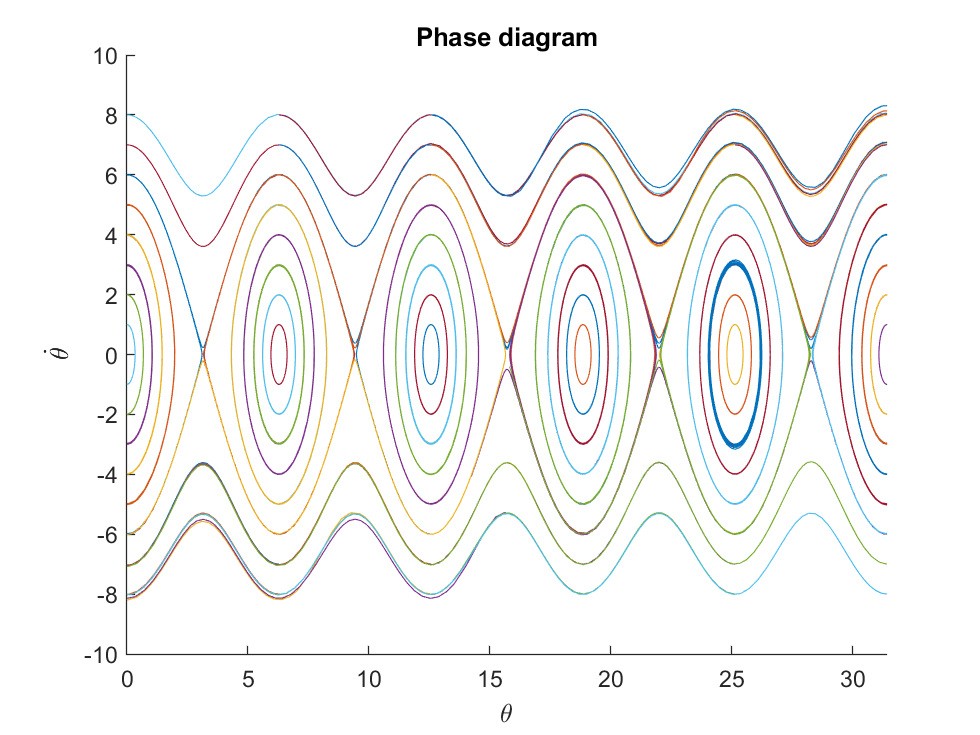

figure
hold on
for thetad0 = -8:8
    for theta0 = 0:2*pi:10*pi
    [t,w] = pendulum_sin(R,theta0,thetad0);
    plot(w(:,1),w(:,2))
    end
end
xlim([0 10*pi])
xlabel('\theta')
ylabel('$\dot{\theta}$','interpreter','latex')
title('Phase diagram')

(d)

Yes, there are different paths for differnt energy. For the same energy, paths are overlapped.

The total energy.

ecllipse or wave.

Clockwise, since dx = y.